%% Initialize time array
minTimeStr = '2015-05-26 00:00';
maxTimeStr = '2015-05-26 23:59';
time = datenum(minTimeStr):(30/(24*60)):datenum(maxTimeStr);

altKmRange = [350, 350, 1];
glat = 65;
glon = -147.5;
setSamplePlot = false;

for iTime = 1:1:length(time)
%     data = iri2016f90(time(iTime),altKmRange,glat,glon,setSamplePlot);
    data = iri2016(time(iTime),glat,glon,altKmRange);
    data1 = iri_2016_bak(time(iTime),altKmRange(1),glat,glon);
    Ne(iTime) = data.Ne;
    Ne1(iTime) = data1.Ne;
end

Error using __init__>IRI (line 86)
Python Error: TypeError: object of type 'float' has no len()

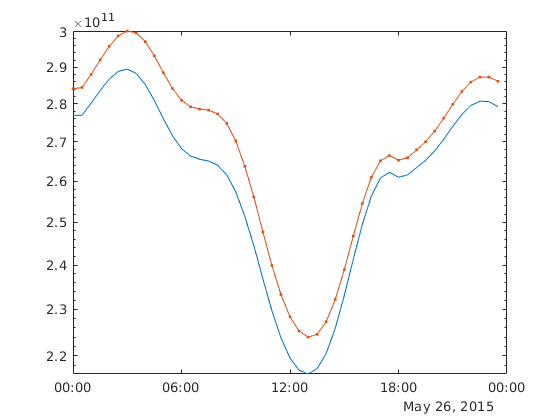

figure;
plot(datetime(time,'ConvertFrom','datenum'),Ne);
hold on;
plot(datetime(time,'ConvertFrom','datenum'),Ne1,'.-');
set(gca,'YScale','log');

%% Plotting All species
time1 = datenum(minTimeStr);
tic
data = iri2016f90(time1,80:1:90,glat,glon,false);
toc

Elapsed time is 0.087821 seconds.
